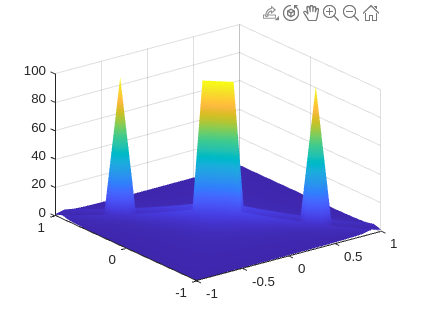

x=-1e3:1e2:-100;
x = [x,-90:10:-10];
x = [x,-9:1:-1];
x = [x,-0.9:0.1:-0.1];
x = [x,-0.09:0.01:0];
x = [x,0.01:0.01:0.1];
x = [x,0.2:0.1:1];
x = [x,2:1:10];
x = [x,20:10:100];
x = [x,200:100:1000]; % x范围

y=x;

[xx,yy]=meshgrid(x,y); %构成格点矩阵

S_soft = calsoftmin(xx, yy);
S_real = max(xx,yy);

err = abs(S_soft - S_real);
err_relative = err;
m = calmean(xx, yy);

err_relative = err ./ abs(m);
err_relative(find(abs(err_relative)==inf))=1;
% err(find(abs(err)==inf))=1;
err_relative(find(abs(err_relative) > 100))=100;

surf(xx,yy,err_relative);
shading interp;
axis([-1,1,-1,1,0,100])

function S = calsoftmin(f1, f2)
    alpha = 1;
    sum_exp = exp(alpha * f1) + exp(alpha * f2); 
    S = 1/alpha * log(sum_exp);
end

function s=calmean(x, y) 
    s = (x+y)/2.0;
end
